clear 
clc

steerAng = 35;
fs = 41.667e3;

fmax = 20.8e3;
%freqList = linspace(0, fmax, 209) % 0 til fmax med 100 Hz hop
freqList = linspace(0, fmax-300, 42) % 0 til 20.5 kHz med 500 Hz hop

freqList =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000        5500        6000        6500        7000        7500        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       16500       17000       17500       18000       18500       19000       19500       20000       20500


freqList(1) = 50;

degList = (1:5:180) - 1

degList =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175


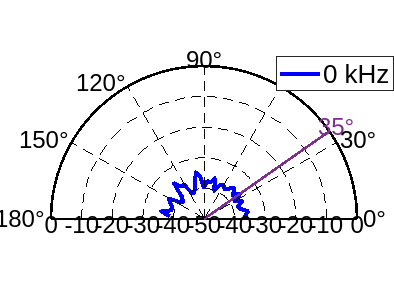

numTries = 3;

%for d = minDegs:maxDegs 
for d = 1:length(degList)
    for f = 1:length(freqList)
        outputPowerTemp = 0;
        nonInvalid = 0;
        for t = 1:numTries
            fileID = fopen('degree_' + string(degList(d)) ...
                + '_freq_' + string(freqList(f)) + '_num_' + string(t-1));
            data = fread(fileID,'single');  
            data = data/(power(2,31)-1);
            numMics = 8;
            numSamples = 190;
            onePacketLength = numSamples*numMics;
            numPacketsInData = floor(length(data)/onePacketLength);
            beamformData = zeros(numSamples,1);
            for i = 1:numPacketsInData
                beamformData = [beamformData; data((1+numSamples*7*i):numSamples*7*i+numSamples)];
            end
            beamformData = beamformData(numSamples+1:end,:)';
            if max(beamformData) < 1
                outputPowerTemp = outputPowerTemp + mean(beamformData.^2);
                nonInvalid = nonInvalid + 1;
            end
        end % for numTries
        if nonInvalid > 0
            outputPower(d,f) = outputPowerTemp/nonInvalid;
        else
            outputPower(d,f) = nan;
        end
    end % for freqs
end % for degs

outputPowerDB = pow2db(outputPower);
        
circPlot(freqList(1), degList.*pi/180, outputPowerDB(:,1)', steerAng)

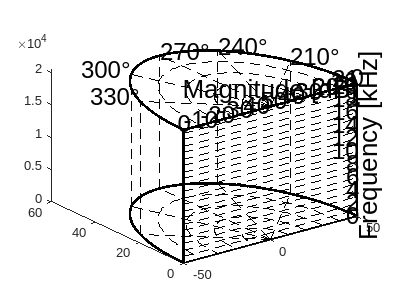

Arrays have incompatible sizes for this operation.

Error in pol2cart (line 23)
x = r.*cos(th);

Error in cylindricalPlot (line 71)
    [X,Y] = pol2cart(THETA,logOutput+mindB); %theta_plot

Related documentation

cylindricalPlot(freqList, degList.*pi/180, outputPowerDB', 180-steerAng, [180, 10])